# Semantic Segmentation Using Pascal-VOC dataset

This example shows how to train a semantic segmentation network using deep learning. This example was a modified version of the Matlab official document entitled [Semantic Segmentation Using Deep Learning](https://jp.mathworks.com/help/vision/examples/semantic-segmentation-using-deep-learning.html) [1]. A semantic segmentation network classifies every pixel in an image, resulting in an image that is segmented by class as shown below. 

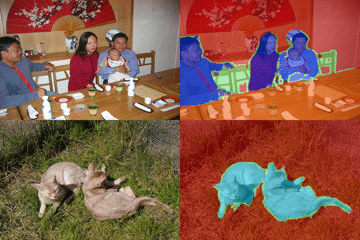

     To illustrate the training procedure, this example trains Deeplab v3+ [2], one type of convolutional neural network (CNN) designed for semantic image segmentation. This example uses the dataset in [Visual Object Classes Challenge 2012 (VOC2012)](http://host.robots.ox.ac.uk/pascal/VOC/voc2012/index.html) [3]. To run this code, please down load the dataset available at  [3]. 

[1]  [Semantic Segmentation Using Deep Learning](https://jp.mathworks.com/help/vision/examples/semantic-segmentation-using-deep-learning.html)

[2] Chen, Liang-Chieh et al. “Encoder-Decoder with Atrous Separable Convolution for Semantic Image Segmentation.” ECCV (2018).

[3]  [Visual Object Classes Challenge 2012 (VOC2012)](http://host.robots.ox.ac.uk/pascal/VOC/voc2012/index.html)

## Load CamVid Pixel-Labeled Images

Please run this code after down-loading the Pascal-VOC data from [2]. Unzip and change the directly as shown below. The down-loaded data can be unfrozen into the folders as shown below. The annotated labels were stored in the folder of SegmentationClass. The pixel values in the png images in the Segmentation Class folder corresponds to class ID. Each class ID represents each class. 

     Use [`pixelLabelDatastore`](docid:vision_ref.mw_c2246553-ba4a-4bad-aad4-6ab8fa2f7f2d) to load CamVid pixel label image data. A `pixelLabelDatastore` encapsulates the pixel label data and the label ID to a class name mapping. Use the classes and label IDs to create the `pixelLabelDatastore.`

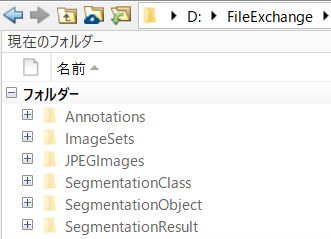

clear;clc;close all

The labeled images are stored in `SegmentationClass` folder with `png` format. 

labeledImg=imread('./SegmentationClass/2007_003251.png');

The edges have the intensity of 255 while each object ID is like 3, 5, 10. Just using imshow does not depict the labeled image well. Use `label2rgb` function to convert label matrix into RGB image. 

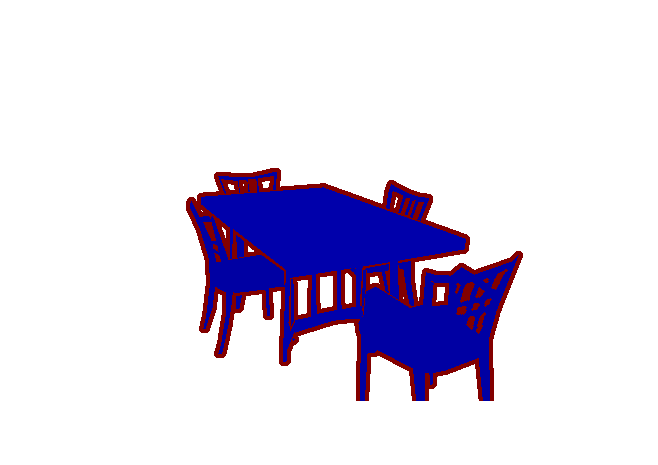

RGB= label2rgb(labeledImg);
figure;imshow(RGB)

## Create datastore for images and labels

classes={'background','aeroplane','bicycle','bird','boat','bottle','bus','car','cat','chair','cow','diningtable','dog', ...
    'horse','motorbike','person','potted_plant','sheep','sofa','train','tv_monitor','void'};
labelIDs=[0:20,255];
pxds = pixelLabelDatastore('SegmentationClass',classes,labelIDs);

The RGB image was stored in `SegmentationClass` folder. The label image and its RGB image can be linked as follows and store the RGB image into image datastore. 

imgAddress=strcat(extractBefore(pxds.Files,'SegmentationClass'),'JPEGImages',extractBetween(pxds.Files,'SegmentationClass','png'),'jpg');
imds=imageDatastore(imgAddress);

## Display one example

Read and display one of the pixel-labeled images by overlaying it on top of an image.

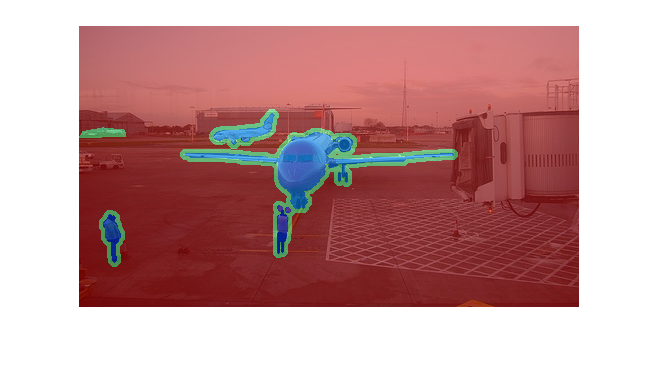

I = readimage(imds,1);
C = readimage(pxds,1);
B = labeloverlay(I,C);
figure;imshow(B)

## Analyze Dataset Statistics

To see the distribution of class labels in the CamVid dataset, use[ `countEachLabel`](docid:vision_ref.mw_1c600e69-1a15-4538-9629-7bceaafbd4e7). This function counts the number of pixels by class label.

tbl = countEachLabel(pxds)

tbl = 22×3 table
         Name          PixelCount    ImagePixelCount
    _______________    __________    _______________

    {'background' }    3.6156e+08      5.1977e+08   
    {'aeroplane'  }    3.7044e+06      3.0556e+07   
    {'bicycle'    }    1.5711e+06      2.5999e+07   
    {'bird'       }    4.3841e+06      3.7509e+07   
    {'boat'       }    2.8629e+06      2.6733e+07   
    {'bottle'     }     3.439e+06      3.3328e+07   
    {'bus'        }    8.6964e+06       2.703e+07   
    {'car'        }    7.0882e+06      4.4885e+07   
    {'cat'        }    1.2473e+07      4.5464e+07   
    {'chair'      }    4.9753e+06      4.9342e+07   
    {'cow'        }    5.0278e+06      2.4279e+07   
    {'diningtable'}    6.2464e+06       2.879e+07   
    {'dog'        }    9.3793e+06      4.4853e+07   
    {'horse'      }    4.9257e+06      2.5898e+07   
    {'motorbike'  }    5.4761e+06      2.8316e+07   
    {'person'     }    2.4995e+07      1.5833e+08   


Visualize the pixel counts by class.

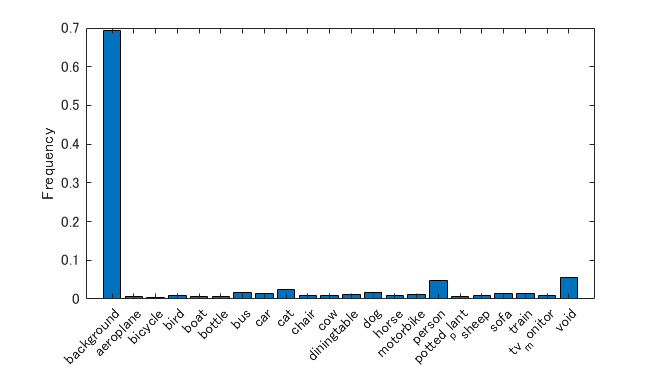

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

## Prepare Training, Validation, and Test Sets

`Deeplab v3+` is trained using 80% of the images from the dataset. The rest of the images are split evenly in 10% and 10% for validation and testing respectively. The following code randomly splits the image and pixel label data into a training, validation and test set.

[imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionPascalVOCData(imds,pxds,labelIDs);

## Confirm the number of images at each dataset

The 80/10/10 split results in the following number of training, validation and test images:

numTrainingImages = numel(imdsTrain.Files)

numTrainingImages = 2330

numValImages = numel(imdsVal.Files)

numValImages = 291

numTestingImages = numel(imdsTest.Files)

numTestingImages = 292

## Create the Network

Use the `deeplabv3plusLayers` function to create a DeepLab v3+ network based on `ResNet-18`. The SegNet and U-Net can be used for the semantic segmentation. Please activate the code in this section if you want to try them. 

% Specify the network image size. This is typically the same as the traing image sizes.
imageSize = [240 360 3];

% Specify the number of classes.
numClasses = numel(classes);

% Create DeepLab v3+.
lgraph = deeplabv3plusLayers(imageSize, numClasses, 'resnet18');
% lgraph = segnetLayers(imageSize,numClasses,3)
% lgraph = unetLayers(imageSize,numClasses,"EncoderDepth",4);

Specify the class weights using a [ `pixelClassificationLayer`](docid:vision_ref.mw_783aebd8-1ff1-4bc6-8508-90c8b71fca32).

pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name);
lgraph = replaceLayer(lgraph,'classification',pxLayer);

## Data Augmentation

Data augmentation is used during training to provide more examples to the network because it helps improve the accuracy of the network. Here, random left/right reflection and random X/Y translation of +/- 10 pixels is used for data augmentation. Use the [`imageDataAugmenter`](docid:nnet_ref.mw_bb6aac9c-0a3d-4700-b4f9-82088d9ad021) to specify these data augmentation parameters.

augmenter = imageDataAugmenter('RandXReflection',false,...
    'RandXTranslation',[-5 5],'RandYTranslation',[-5 5]);

## Select Training Options

The optimization algorithm used for training is stochastic gradient descent with momentum (SGDM). Use [`trainingOptions`](docid:nnet_ref.bu59f0q) to specify the hyper-parameters used for SGDM.

% Define validation data.
pximdsVal = pixelLabelImageDatastore(imdsVal,pxdsVal,'DataAugmentation',augmenter,'OutputSizeMode',"resize",'OutputSize',[240 360]);

% Define training options. 
options = trainingOptions('sgdm', ...% optimizere
    'LearnRateSchedule','piecewise',...% learning rate is reduced every epoch. if you make the rate constant over the traning process, please specify as "none". 
    'LearnRateDropPeriod',10,...% reduce the learning rate at the factor of 0.3 every 10 epoch
    'LearnRateDropFactor',0.3,...% reduce the learning rate at the factor of 0.3
    'InitialLearnRate',1e-2, ...% specify initial learning rate
    'L2Regularization',0.0001, ...% L2 regularization 
    'ValidationData',pximdsVal,...% validation data
    'MaxEpochs',50, ...% max epoch  
    'MiniBatchSize',16, ...% mini-batch size
    'Shuffle','every-epoch', ...% shuffle the data at each epoch
    'VerboseFrequency',500,...% display the training status at every 500 iterations when using trainNetwork
    'Plots','training-progress',...% display the training curve
    'ValidationPatience', Inf); % when the validation accuracy is not decreased for 10 times in a row, training stops

## Start Training

Combine the training data and data augmentation selections using [`pixelLabelImageDatastore`](docid:vision_ref.mw_da0f190c-63ec-42a7-9476-3ebff78f3b81). The `pixelLabelImageDatastore` reads batches of training data, applies data augmentation, and sends the augmented data to the training algorithm. 

pximds = pixelLabelImageDatastore(imdsTrain,pxdsTrain, ...
    'DataAugmentation',augmenter,'OutputSizeMode',"resize",'OutputSize',[240 360]);

## Training the network

Start training using [`trainNetwork`](docid:nnet_ref.bu6sn4c) if the `doTraining` flag is true. Otherwise, load a pretrained network.

単一の GPU で学習中。
入力データの正規化を初期化しています。


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチの精度　　｜　　検証精度　　｜　　ミニバッチ損失　　｜　　検証損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　　　　１　｜　　　　１　｜　　　　　００：００：４７　｜　　　　　　２．４１％　｜　６０．０６％　｜　　　　３．５５６２　｜　１．９８０６　｜　　０．０１００　｜


｜　　　　　　１　｜　　　５０　｜　　　　　００：０１：５１　｜　　　　　７５．７４％　｜　７２．１２％　｜　　　　０．８９７４　｜　１．０２６０　｜　　０．０１００　｜


｜　　　　　　１　｜　　１００　｜　　　　　００：０２：５１　｜　　　　　７５．６０％　｜　７５．０５％　｜　　　　０．７４７６　｜　０．８４８２　｜　　０．０１００　｜


｜　　　　　　２　｜　　１５０　｜　　　　　００：０３：５２　｜　　　　　８２．０４％　｜　７６．９６％　｜　　　　０．５８７７　｜　０．８０１９　｜　　０．０１００　｜


｜　　　　　　２　｜　　２００　｜　　　　　００：０４：５１　｜　　　　　８４．２６％　｜　７７．１２％　｜　　　　０．４８１０　｜　０．７７３５　｜　　０．０１００　｜


｜　　　　　　２　｜　　２５０　｜　　　　　００：０５：４８　｜　　　　　８６．５２％　｜　７８．１７％　｜　　　　０．４５３６　｜　０．７２６９　｜　　０．０１００　｜


｜　　　　　　３　｜　　３００　｜　　　　　００：０６：４６　｜　　　　　７６．８９％　｜　７９．１９％　｜　　　　０．７１１２　｜　０．６６３７　｜　　０．０１００　｜


｜　　　　　　３　｜　　３５０　｜　　　　　００：０７：４６　｜　　　　　８５．０５％　｜　７９．７４％　｜　　　　０．４６８７　｜　０．６８０７　｜　　０．０１００　｜


｜　　　　　　３　｜　　４００　｜　　　　　００：０８：４４　｜　　　　　８５．６５％　｜　７９．９７％　｜　　　　０．４３１１　｜　０．６６４２　｜　　０．０１００　｜


｜　　　　　　４　｜　　４５０　｜　　　　　００：０９：４１　｜　　　　　８５．５８％　｜　８１．０３％　｜　　　　０．３９１４　｜　０．６４２１　｜　　０．０１００　｜


｜　　　　　　４　｜　　５００　｜　　　　　００：１０：４０　｜　　　　　８８．０２％　｜　８０．９７％　｜　　　　０．３５９７　｜　０．６３８４　｜　　０．０１００　｜


｜　　　　　　４　｜　　５５０　｜　　　　　００：１１：４０　｜　　　　　８３．８７％　｜　８０．６８％　｜　　　　０．４９７８　｜　０．６３６１　｜　　０．０１００　｜


｜　　　　　　５　｜　　６００　｜　　　　　００：１２：３９　｜　　　　　８９．０１％　｜　８１．８４％　｜　　　　０．３５２１　｜　０．５９７７　｜　　０．０１００　｜


｜　　　　　　５　｜　　６５０　｜　　　　　００：１３：４３　｜　　　　　８８．０３％　｜　８０．９１％　｜　　　　０．３４０８　｜　０．６３７８　｜　　０．０１００　｜


｜　　　　　　５　｜　　７００　｜　　　　　００：１４：４７　｜　　　　　８９．９９％　｜　８０．４４％　｜　　　　０．３０４９　｜　０．７５１６　｜　　０．０１００　｜


｜　　　　　　６　｜　　７５０　｜　　　　　００：１５：５１　｜　　　　　８８．０３％　｜　８１．４４％　｜　　　　０．３２１４　｜　０．６４２６　｜　　０．０１００　｜


｜　　　　　　６　｜　　８００　｜　　　　　００：１６：５４　｜　　　　　８１．４２％　｜　８１．５２％　｜　　　　０．５２３０　｜　０．６９６３　｜　　０．０１００　｜


｜　　　　　　６　｜　　８５０　｜　　　　　００：１７：５９　｜　　　　　８９．９５％　｜　８１．６９％　｜　　　　０．２９１３　｜　０．６３３３　｜　　０．０１００　｜


｜　　　　　　７　｜　　９００　｜　　　　　００：１９：３８　｜　　　　　８７．８３％　｜　８１．８９％　｜　　　　０．３２０８　｜　０．６３２０　｜　　０．０１００　｜


｜　　　　　　７　｜　　９５０　｜　　　　　００：２０：４１　｜　　　　　９２．４５％　｜　８２．２５％　｜　　　　０．２１６１　｜　０．６４０７　｜　　０．０１００　｜


｜　　　　　　７　｜　１０００　｜　　　　　００：２１：４７　｜　　　　　９１．６７％　｜　８１．７６％　｜　　　　０．２３０４　｜　０．６５６１　｜　　０．０１００　｜


｜　　　　　　８　｜　１０５０　｜　　　　　００：２２：５６　｜　　　　　８９．２０％　｜　８２．５８％　｜　　　　０．３０１５　｜　０．６５４７　｜　　０．０１００　｜


｜　　　　　　８　｜　１１００　｜　　　　　００：２３：５５　｜　　　　　９１．３５％　｜　８２．２６％　｜　　　　０．２４１２　｜　０．６６９０　｜　　０．０１００　｜


｜　　　　　　８　｜　１１５０　｜　　　　　００：２４：５７　｜　　　　　８７．０５％　｜　８２．８２％　｜　　　　０．３６０２　｜　０．６５３５　｜　　０．０１００　｜


｜　　　　　　９　｜　１２００　｜　　　　　００：２５：５７　｜　　　　　９０．８６％　｜　８２．１８％　｜　　　　０．２４４０　｜　０．７１２６　｜　　０．０１００　｜


｜　　　　　　９　｜　１２５０　｜　　　　　００：２６：５６　｜　　　　　８８．９２％　｜　８２．４０％　｜　　　　０．３１３８　｜　０．６６６４　｜　　０．０１００　｜


｜　　　　　　９　｜　１３００　｜　　　　　００：２７：５７　｜　　　　　９１．３０％　｜　８２．９３％　｜　　　　０．２５９６　｜　０．７０２９　｜　　０．０１００　｜


｜　　　　　１０　｜　１３５０　｜　　　　　００：２８：５８　｜　　　　　９３．９３％　｜　８３．４４％　｜　　　　０．１７８１　｜　０．６３３１　｜　　０．０１００　｜


｜　　　　　１０　｜　１４００　｜　　　　　００：３０：０４　｜　　　　　９１．７７％　｜　８３．７５％　｜　　　　０．２２３７　｜　０．６６５４　｜　　０．０１００　｜


｜　　　　　１０　｜　１４５０　｜　　　　　００：３１：０７　｜　　　　　９２．４６％　｜　８３．６０％　｜　　　　０．２１０６　｜　０．６７４０　｜　　０．０１００　｜


｜　　　　　１１　｜　１５００　｜　　　　　００：３２：０７　｜　　　　　９２．９２％　｜　８３．５３％　｜　　　　０．１８５８　｜　０．６７６９　｜　　０．００３０　｜


｜　　　　　１１　｜　１５５０　｜　　　　　００：３３：０５　｜　　　　　９４．０６％　｜　８３．３３％　｜　　　　０．１５５０　｜　０．６６３１　｜　　０．００３０　｜


｜　　　　　１２　｜　１６００　｜　　　　　００：３４：０３　｜　　　　　９４．０５％　｜　８３．９１％　｜　　　　０．１５５２　｜　０．６３３７　｜　　０．００３０　｜


｜　　　　　１２　｜　１６５０　｜　　　　　００：３５：０１　｜　　　　　９３．８８％　｜　８４．０１％　｜　　　　０．１６３９　｜　０．６４８６　｜　　０．００３０　｜


｜　　　　　１２　｜　１７００　｜　　　　　００：３６：０９　｜　　　　　９２．７７％　｜　８４．０５％　｜　　　　０．１９６７　｜　０．６４６２　｜　　０．００３０　｜


｜　　　　　１３　｜　１７５０　｜　　　　　００：３７：１０　｜　　　　　９２．１７％　｜　８３．２７％　｜　　　　０．２００９　｜　０．６９６０　｜　　０．００３０　｜


｜　　　　　１３　｜　１８００　｜　　　　　００：３８：０８　｜　　　　　９１．２５％　｜　８３．６２％　｜　　　　０．２２４４　｜　０．６８８９　｜　　０．００３０　｜


｜　　　　　１３　｜　１８５０　｜　　　　　０６：４９：４２　｜　　　　　９３．４３％　｜　８３．９０％　｜　　　　０．１７６２　｜　０．６５４４　｜　　０．００３０　｜


｜　　　　　１４　｜　１９００　｜　　　　　０６：５０：５５　｜　　　　　９５．０４％　｜　８３．８５％　｜　　　　０．１３０７　｜　０．６８１６　｜　　０．００３０　｜


｜　　　　　１４　｜　１９５０　｜　　　　　０６：５２：１８　｜　　　　　９３．６９％　｜　８３．６２％　｜　　　　０．１５８８　｜　０．６９２０　｜　　０．００３０　｜


｜　　　　　１４　｜　２０００　｜　　　　　０６：５３：３２　｜　　　　　９３．４６％　｜　８３．９１％　｜　　　　０．１７９２　｜　０．６６９５　｜　　０．００３０　｜


｜　　　　　１５　｜　２０５０　｜　　　　　０６：５４：４８　｜　　　　　９３．２０％　｜　８３．８６％　｜　　　　０．１８５４　｜　０．６９３９　｜　　０．００３０　｜


｜　　　　　１５　｜　２１００　｜　　　　　０６：５５：５４　｜　　　　　９４．４４％　｜　８３．８６％　｜　　　　０．１３５９　｜　０．６８０４　｜　　０．００３０　｜


｜　　　　　１５　｜　２１５０　｜　　　　　０６：５６：５３　｜　　　　　９３．９３％　｜　８３．９２％　｜　　　　０．１５６８　｜　０．６８６５　｜　　０．００３０　｜


｜　　　　　１６　｜　２２００　｜　　　　　０６：５７：５４　｜　　　　　９４．９２％　｜　８３．５９％　｜　　　　０．１３１５　｜　０．６７９５　｜　　０．００３０　｜


｜　　　　　１６　｜　２２５０　｜　　　　　０６：５８：５７　｜　　　　　９２．７９％　｜　８３．１６％　｜　　　　０．１８７３　｜　０．７０８３　｜　　０．００３０　｜


｜　　　　　１６　｜　２３００　｜　　　　　０６：５９：５９　｜　　　　　９３．４５％　｜　８３．５３％　｜　　　　０．１７３６　｜　０．７２７０　｜　　０．００３０　｜


｜　　　　　１７　｜　２３５０　｜　　　　　０７：０１：０７　｜　　　　　９５．１２％　｜　８３．６５％　｜　　　　０．１２７４　｜　０．７０４１　｜　　０．００３０　｜


｜　　　　　１７　｜　２４００　｜　　　　　０７：０２：１０　｜　　　　　９４．２３％　｜　８３．９９％　｜　　　　０．１５１８　｜　０．６８７６　｜　　０．００３０　｜


｜　　　　　１７　｜　２４５０　｜　　　　　０７：０３：１１　｜　　　　　９４．９９％　｜　８３．６４％　｜　　　　０．１２２７　｜　０．６８１９　｜　　０．００３０　｜


｜　　　　　１８　｜　２５００　｜　　　　　０７：０４：１７　｜　　　　　９２．６４％　｜　８３．８３％　｜　　　　０．１８９９　｜　０．６９４４　｜　　０．００３０　｜


｜　　　　　１８　｜　２５５０　｜　　　　　０７：０５：１７　｜　　　　　９３．６２％　｜　８３．８６％　｜　　　　０．１６３８　｜　０．７０８８　｜　　０．００３０　｜


｜　　　　　１８　｜　２６００　｜　　　　　０７：０６：１７　｜　　　　　９４．６６％　｜　８４．０１％　｜　　　　０．１３６５　｜　０．７００６　｜　　０．００３０　｜


｜　　　　　１９　｜　２６５０　｜　　　　　０７：０７：２４　｜　　　　　９５．６９％　｜　８３．６６％　｜　　　　０．１１４６　｜　０．７３１９　｜　　０．００３０　｜


｜　　　　　１９　｜　２７００　｜　　　　　０７：０８：２７　｜　　　　　９３．７５％　｜　８３．６８％　｜　　　　０．１６１７　｜　０．７０３５　｜　　０．００３０　｜


｜　　　　　１９　｜　２７５０　｜　　　　　０７：０９：２８　｜　　　　　９５．２７％　｜　８３．２４％　｜　　　　０．１２３８　｜　０．７１１５　｜　　０．００３０　｜


｜　　　　　２０　｜　２８００　｜　　　　　０７：１０：２９　｜　　　　　９２．７８％　｜　８３．５４％　｜　　　　０．１８２９　｜　０．７３１９　｜　　０．００３０　｜


｜　　　　　２０　｜　２８５０　｜　　　　　０７：１１：２９　｜　　　　　９５．３３％　｜　８３．９０％　｜　　　　０．１２２６　｜　０．７０８８　｜　　０．００３０　｜


｜　　　　　２０　｜　２９００　｜　　　　　０７：１２：２９　｜　　　　　９５．５０％　｜　８３．９７％　｜　　　　０．１２０２　｜　０．６９６４　｜　　０．００３０　｜


｜　　　　　２１　｜　２９５０　｜　　　　　０７：１３：３０　｜　　　　　９４．８２％　｜　８３．７２％　｜　　　　０．１３５４　｜　０．７１６１　｜　　０．０００９　｜


｜　　　　　２１　｜　３０００　｜　　　　　０７：１４：３０　｜　　　　　９５．５６％　｜　８３．８７％　｜　　　　０．１１２７　｜　０．７００５　｜　　０．０００９　｜


｜　　　　　２２　｜　３０５０　｜　　　　　０７：１５：２８　｜　　　　　９２．３９％　｜　８４．０２％　｜　　　　０．１９１４　｜　０．６９８１　｜　　０．０００９　｜


｜　　　　　２２　｜　３１００　｜　　　　　０７：１６：２７　｜　　　　　９５．０２％　｜　８３．５７％　｜　　　　０．１２３５　｜　０．７１８６　｜　　０．０００９　｜


｜　　　　　２２　｜　３１５０　｜　　　　　０７：１７：２５　｜　　　　　９６．０９％　｜　８３．９４％　｜　　　　０．１０２０　｜　０．６９０１　｜　　０．０００９　｜


｜　　　　　２３　｜　３２００　｜　　　　　０７：１８：３０　｜　　　　　９４．４１％　｜　８３．７９％　｜　　　　０．１３８３　｜　０．７２６３　｜　　０．０００９　｜


｜　　　　　２３　｜　３２５０　｜　　　　　０７：１９：２８　｜　　　　　９３．５２％　｜　８３．４８％　｜　　　　０．１６４７　｜　０．７１７７　｜　　０．０００９　｜


｜　　　　　２３　｜　３３００　｜　　　　　０７：２０：２６　｜　　　　　９５．７４％　｜　８３．７０％　｜　　　　０．１１４１　｜　０．７１３５　｜　　０．０００９　｜


｜　　　　　２４　｜　３３５０　｜　　　　　０７：２１：２５　｜　　　　　９４．７２％　｜　８３．８５％　｜　　　　０．１４０６　｜　０．６９７４　｜　　０．０００９　｜


｜　　　　　２４　｜　３４００　｜　　　　　０７：２２：２３　｜　　　　　９４．８１％　｜　８３．９４％　｜　　　　０．１３０７　｜　０．７１５５　｜　　０．０００９　｜


｜　　　　　２４　｜　３４５０　｜　　　　　０７：２３：２２　｜　　　　　９５．５１％　｜　８３．８６％　｜　　　　０．１１６８　｜　０．７３７０　｜　　０．０００９　｜


｜　　　　　２５　｜　３５００　｜　　　　　０７：２４：２１　｜　　　　　９５．１３％　｜　８３．７８％　｜　　　　０．１２６４　｜　０．７２４１　｜　　０．０００９　｜


｜　　　　　２５　｜　３５５０　｜　　　　　０７：２５：２３　｜　　　　　９４．３０％　｜　８３．９３％　｜　　　　０．１４６５　｜　０．７１５８　｜　　０．０００９　｜


｜　　　　　２５　｜　３６００　｜　　　　　０７：２６：２２　｜　　　　　９４．３６％　｜　８３．６１％　｜　　　　０．１３７９　｜　０．７３２１　｜　　０．０００９　｜


｜　　　　　２６　｜　３６５０　｜　　　　　０７：２７：２０　｜　　　　　９２．０４％　｜　８３．８２％　｜　　　　０．２０４８　｜　０．７４１８　｜　　０．０００９　｜


｜　　　　　２６　｜　３７００　｜　　　　　０７：２８：１８　｜　　　　　９４．６３％　｜　８４．１５％　｜　　　　０．１３６１　｜　０．６９８８　｜　　０．０００９　｜


｜　　　　　２６　｜　３７５０　｜　　　　　０７：２９：２３　｜　　　　　９４．７８％　｜　８３．８４％　｜　　　　０．１３４２　｜　０．７２９９　｜　　０．０００９　｜


｜　　　　　２７　｜　３８００　｜　　　　　０７：３０：２４　｜　　　　　９５．４７％　｜　８３．７６％　｜　　　　０．１１０６　｜　０．７４４３　｜　　０．０００９　｜


｜　　　　　２７　｜　３８５０　｜　　　　　０７：３１：２５　｜　　　　　９４．７９％　｜　８３．９７％　｜　　　　０．１３７７　｜　０．７１３１　｜　　０．０００９　｜


｜　　　　　２７　｜　３９００　｜　　　　　０７：３２：２５　｜　　　　　９５．５６％　｜　８４．３３％　｜　　　　０．１１６７　｜　０．６９５３　｜　　０．０００９　｜


｜　　　　　２８　｜　３９５０　｜　　　　　０７：３３：２８　｜　　　　　９６．２５％　｜　８４．０６％　｜　　　　０．０９５６　｜　０．７１９３　｜　　０．０００９　｜


｜　　　　　２８　｜　４０００　｜　　　　　０７：３４：２８　｜　　　　　９４．８１％　｜　８３．６９％　｜　　　　０．１３２４　｜　０．７５０１　｜　　０．０００９　｜


｜　　　　　２８　｜　４０５０　｜　　　　　０７：３５：３２　｜　　　　　９５．１０％　｜　８４．１５％　｜　　　　０．１２５５　｜　０．７１６６　｜　　０．０００９　｜


｜　　　　　２９　｜　４１００　｜　　　　　０７：３６：３５　｜　　　　　９４．９６％　｜　８４．１３％　｜　　　　０．１２４１　｜　０．７０８５　｜　　０．０００９　｜


｜　　　　　２９　｜　４１５０　｜　　　　　０７：３７：３８　｜　　　　　９５．１１％　｜　８３．９６％　｜　　　　０．１２１７　｜　０．７１５４　｜　　０．０００９　｜


｜　　　　　２９　｜　４２００　｜　　　　　０７：３８：３９　｜　　　　　９３．９５％　｜　８３．８５％　｜　　　　０．１５０６　｜　０．７５０９　｜　　０．０００９　｜


｜　　　　　３０　｜　４２５０　｜　　　　　０７：３９：４２　｜　　　　　９４．０７％　｜　８４．０３％　｜　　　　０．１５２２　｜　０．７１９５　｜　　０．０００９　｜


｜　　　　　３０　｜　４３００　｜　　　　　０７：４０：５１　｜　　　　　９３．７２％　｜　８３．６２％　｜　　　　０．１５７１　｜　０．７４５０　｜　　０．０００９　｜


｜　　　　　３０　｜　４３５０　｜　　　　　０７：４１：５８　｜　　　　　９５．４８％　｜　８３．８４％　｜　　　　０．１１４７　｜　０．７５８９　｜　　０．０００９　｜


｜　　　　　３１　｜　４４００　｜　　　　　０７：４３：０４　｜　　　　　９５．５２％　｜　８４．３５％　｜　　　　０．１１８０　｜　０．７１０６　｜　　０．０００３　｜


｜　　　　　３１　｜　４４５０　｜　　　　　０７：４４：０６　｜　　　　　９２．８０％　｜　８３．７２％　｜　　　　０．１８３８　｜　０．７３４６　｜　　０．０００３　｜


｜　　　　　３２　｜　４５００　｜　　　　　０７：４５：１１　｜　　　　　９５．４３％　｜　８３．８１％　｜　　　　０．１１２１　｜　０．７２８０　｜　　０．０００３　｜


｜　　　　　３２　｜　４５５０　｜　　　　　０７：４６：１７　｜　　　　　９５．９６％　｜　８３．９６％　｜　　　　０．１０６１　｜　０．７２６３　｜　　０．０００３　｜


｜　　　　　３２　｜　４６００　｜　　　　　０７：４７：２８　｜　　　　　９５．８３％　｜　８４．０９％　｜　　　　０．１０５１　｜　０．７１８８　｜　　０．０００３　｜


｜　　　　　３３　｜　４６５０　｜　　　　　０７：４８：４５　｜　　　　　９５．０６％　｜　８３．７７％　｜　　　　０．１２８６　｜　０．７６８０　｜　　０．０００３　｜


｜　　　　　３３　｜　４７００　｜　　　　　０７：４９：５２　｜　　　　　９４．４３％　｜　８３．８７％　｜　　　　０．１４１３　｜　０．７３０６　｜　　０．０００３　｜


｜　　　　　３３　｜　４７５０　｜　　　　　０７：５０：５７　｜　　　　　９５．２２％　｜　８３．９４％　｜　　　　０．１２１１　｜　０．７４０６　｜　　０．０００３　｜


｜　　　　　３４　｜　４８００　｜　　　　　０７：５２：０９　｜　　　　　９５．４６％　｜　８３．９５％　｜　　　　０．１１４２　｜　０．７１３７　｜　　０．０００３　｜


｜　　　　　３４　｜　４８５０　｜　　　　　０７：５３：１５　｜　　　　　９４．２３％　｜　８４．２７％　｜　　　　０．１４８０　｜　０．７１３３　｜　　０．０００３　｜


｜　　　　　３４　｜　４９００　｜　　　　　０７：５４：２４　｜　　　　　９５．６８％　｜　８３．７１％　｜　　　　０．１１０７　｜　０．７４８２　｜　　０．０００３　｜


｜　　　　　３５　｜　４９５０　｜　　　　　０７：５５：３１　｜　　　　　９４．８０％　｜　８３．７４％　｜　　　　０．１２９２　｜　０．７５７７　｜　　０．０００３　｜


｜　　　　　３５　｜　５０００　｜　　　　　０７：５６：４１　｜　　　　　９５．１７％　｜　８３．４６％　｜　　　　０．１２９７　｜　０．７５５２　｜　　０．０００３　｜


｜　　　　　３５　｜　５０５０　｜　　　　　０７：５８：０４　｜　　　　　９５．６９％　｜　８４．２１％　｜　　　　０．１０４９　｜　０．７１５０　｜　　０．０００３　｜


｜　　　　　３６　｜　５１００　｜　　　　　０７：５９：２０　｜　　　　　９５．９１％　｜　８３．４８％　｜　　　　０．１００１　｜　０．７５５６　｜　　０．０００３　｜


｜　　　　　３６　｜　５１５０　｜　　　　　０８：００：４３　｜　　　　　９６．３０％　｜　８３．５３％　｜　　　　０．０９６５　｜　０．７６６２　｜　　０．０００３　｜


｜　　　　　３６　｜　５２００　｜　　　　　０８：０１：５７　｜　　　　　９６．５０％　｜　８３．８７％　｜　　　　０．０８７０　｜　０．７３６２　｜　　０．０００３　｜


｜　　　　　３７　｜　５２５０　｜　　　　　０８：０３：０９　｜　　　　　９６．１５％　｜　８４．２２％　｜　　　　０．０９３５　｜　０．７２９９　｜　　０．０００３　｜


｜　　　　　３７　｜　５３００　｜　　　　　０８：０４：１６　｜　　　　　９３．７８％　｜　８３．７８％　｜　　　　０．１５６９　｜　０．７５６４　｜　　０．０００３　｜


｜　　　　　３７　｜　５３５０　｜　　　　　０８：０５：２５　｜　　　　　９５．０９％　｜　８４．０３％　｜　　　　０．１２４５　｜　０．７６３３　｜　　０．０００３　｜


｜　　　　　３８　｜　５４００　｜　　　　　０８：０６：３０　｜　　　　　９４．６７％　｜　８３．７９％　｜　　　　０．１３７７　｜　０．７３７６　｜　　０．０００３　｜


｜　　　　　３８　｜　５４５０　｜　　　　　０８：０７：３３　｜　　　　　９５．４５％　｜　８３．８９％　｜　　　　０．１１９８　｜　０．７１８５　｜　　０．０００３　｜


｜　　　　　３８　｜　５５００　｜　　　　　０８：０８：３６　｜　　　　　９３．６０％　｜　８３．８１％　｜　　　　０．１５５４　｜　０．７５３２　｜　　０．０００３　｜


｜　　　　　３９　｜　５５５０　｜　　　　　０８：０９：４１　｜　　　　　９４．３９％　｜　８３．８２％　｜　　　　０．１４１７　｜　０．７４６８　｜　　０．０００３　｜


｜　　　　　３９　｜　５６００　｜　　　　　０８：１０：４７　｜　　　　　９５．３９％　｜　８４．０８％　｜　　　　０．１１０９　｜　０．７０９２　｜　　０．０００３　｜


｜　　　　　３９　｜　５６５０　｜　　　　　０８：１１：４６　｜　　　　　９５．４６％　｜　８４．０６％　｜　　　　０．１１８８　｜　０．７３８１　｜　　０．０００３　｜


｜　　　　　４０　｜　５７００　｜　　　　　０８：１２：４６　｜　　　　　９３．４８％　｜　８３．８５％　｜　　　　０．１６６６　｜　０．７２２５　｜　　０．０００３　｜


｜　　　　　４０　｜　５７５０　｜　　　　　０８：１３：４８　｜　　　　　９５．４２％　｜　８３．５２％　｜　　　　０．１１６３　｜　０．７５２７　｜　　０．０００３　｜


｜　　　　　４０　｜　５８００　｜　　　　　０８：１４：５０　｜　　　　　９５．４８％　｜　８３．７８％　｜　　　　０．１１９４　｜　０．７３０３　｜　　０．０００３　｜


｜　　　　　４１　｜　５８５０　｜　　　　　０８：１５：５３　｜　　　　　９５．９１％　｜　８４．１７％　｜　　　　０．１０６７　｜　０．７２１０　｜　８．１０００ｅ－０５　｜


｜　　　　　４１　｜　５９００　｜　　　　　０８：１６：５６　｜　　　　　９５．６３％　｜　８３．９１％　｜　　　　０．１１１８　｜　０．７５２７　｜　８．１０００ｅ－０５　｜


｜　　　　　４２　｜　５９５０　｜　　　　　０８：１８：００　｜　　　　　９３．６９％　｜　８４．１７％　｜　　　　０．１４７４　｜　０．７０５１　｜　８．１０００ｅ－０５　｜


｜　　　　　４２　｜　６０００　｜　　　　　０８：１９：０５　｜　　　　　９５．８４％　｜　８４．０５％　｜　　　　０．１０８１　｜　０．７１４１　｜　８．１０００ｅ－０５　｜


｜　　　　　４２　｜　６０５０　｜　　　　　０８：２０：１０　｜　　　　　９４．８４％　｜　８３．９６％　｜　　　　０．１２９７　｜　０．７３２１　｜　８．１０００ｅ－０５　｜


｜　　　　　４３　｜　６１００　｜　　　　　０８：２１：１５　｜　　　　　９４．５９％　｜　８３．６６％　｜　　　　０．１３５４　｜　０．７４２３　｜　８．１０００ｅ－０５　｜


｜　　　　　４３　｜　６１５０　｜　　　　　０８：２２：２０　｜　　　　　９５．０７％　｜　８４．１１％　｜　　　　０．１２６４　｜　０．７３９２　｜　８．１０００ｅ－０５　｜


｜　　　　　４３　｜　６２００　｜　　　　　０８：２３：２６　｜　　　　　９４．４０％　｜　８４．１４％　｜　　　　０．１３９４　｜　０．７３２４　｜　８．１０００ｅ－０５　｜


｜　　　　　４４　｜　６２５０　｜　　　　　０８：２４：３１　｜　　　　　９６．０４％　｜　８３．７４％　｜　　　　０．０９７１　｜　０．７３０６　｜　８．１０００ｅ－０５　｜


｜　　　　　４４　｜　６３００　｜　　　　　０８：２５：３６　｜　　　　　９４．４７％　｜　８４．１７％　｜　　　　０．１３５４　｜　０．７３２４　｜　８．１０００ｅ－０５　｜


｜　　　　　４４　｜　６３５０　｜　　　　　０８：２６：４２　｜　　　　　９４．４６％　｜　８３．６７％　｜　　　　０．１４２３　｜　０．７５５５　｜　８．１０００ｅ－０５　｜


｜　　　　　４５　｜　６４００　｜　　　　　０８：２７：４８　｜　　　　　９５．０５％　｜　８４．２９％　｜　　　　０．１１９３　｜　０．７１７１　｜　８．１０００ｅ－０５　｜


｜　　　　　４５　｜　６４５０　｜　　　　　０８：２８：５４　｜　　　　　９５．２７％　｜　８４．３０％　｜　　　　０．１２０６　｜　０．７０９３　｜　８．１０００ｅ－０５　｜


｜　　　　　４５　｜　６５００　｜　　　　　０８：３０：００　｜　　　　　９６．１４％　｜　８３．８２％　｜　　　　０．１００２　｜　０．７４６８　｜　８．１０００ｅ－０５　｜


｜　　　　　４６　｜　６５５０　｜　　　　　０８：３１：０６　｜　　　　　９４．５６％　｜　８４．１６％　｜　　　　０．１３０７　｜　０．７１８７　｜　８．１０００ｅ－０５　｜


｜　　　　　４６　｜　６６００　｜　　　　　０８：３２：１１　｜　　　　　９５．００％　｜　８３．９３％　｜　　　　０．１１６４　｜　０．７３０２　｜　８．１０００ｅ－０５　｜


｜　　　　　４６　｜　６６５０　｜　　　　　０８：３３：１７　｜　　　　　９５．７７％　｜　８３．７０％　｜　　　　０．１０８４　｜　０．７３８５　｜　８．１０００ｅ－０５　｜


｜　　　　　４７　｜　６７００　｜　　　　　０８：３４：２３　｜　　　　　９５．６８％　｜　８３．８１％　｜　　　　０．１０９１　｜　０．７５８４　｜　８．１０００ｅ－０５　｜


｜　　　　　４７　｜　６７５０　｜　　　　　０８：３５：２８　｜　　　　　９５．７３％　｜　８３．６５％　｜　　　　０．１１５６　｜　０．７２７８　｜　８．１０００ｅ－０５　｜


｜　　　　　４７　｜　６８００　｜　　　　　０８：３６：３４　｜　　　　　９５．３９％　｜　８４．１２％　｜　　　　０．１１９１　｜　０．７３３０　｜　８．１０００ｅ－０５　｜


｜　　　　　４８　｜　６８５０　｜　　　　　０８：３７：３９　｜　　　　　９５．２４％　｜　８４．４４％　｜　　　　０．１２１７　｜　０．６８９９　｜　８．１０００ｅ－０５　｜


｜　　　　　４８　｜　６９００　｜　　　　　０８：３８：４５　｜　　　　　９４．８７％　｜　８３．９０％　｜　　　　０．１３１５　｜　０．７３９０　｜　８．１０００ｅ－０５　｜


｜　　　　　４８　｜　６９５０　｜　　　　　０８：３９：５０　｜　　　　　９５．６２％　｜　８３．６０％　｜　　　　０．１１０１　｜　０．７６６３　｜　８．１０００ｅ－０５　｜


｜　　　　　４９　｜　７０００　｜　　　　　０８：４０：５６　｜　　　　　９５．０５％　｜　８３．７９％　｜　　　　０．１２３２　｜　０．７３６７　｜　８．１０００ｅ－０５　｜


｜　　　　　４９　｜　７０５０　｜　　　　　０８：４２：０２　｜　　　　　９５．５２％　｜　８３．８５％　｜　　　　０．１１１３　｜　０．７３２３　｜　８．１０００ｅ－０５　｜


｜　　　　　４９　｜　７１００　｜　　　　　０８：４３：０７　｜　　　　　９３．９３％　｜　８３．９２％　｜　　　　０．１５４５　｜　０．７２７７　｜　８．１０００ｅ－０５　｜


｜　　　　　５０　｜　７１５０　｜　　　　　０８：４４：１３　｜　　　　　９４．７６％　｜　８４．０２％　｜　　　　０．１２４６　｜　０．７２８６　｜　８．１０００ｅ－０５　｜


｜　　　　　５０　｜　７２００　｜　　　　　０８：４５：１８　｜　　　　　９５．３２％　｜　８４．２５％　｜　　　　０．１１５７　｜　０．７１１８　｜　８．１０００ｅ－０５　｜


｜　　　　　５０　｜　７２５０　｜　　　　　０８：４６：２３　｜　　　　　９３．４７％　｜　８３．８５％　｜　　　　０．１６３０　｜　０．７５８７　｜　８．１０００ｅ－０５　｜


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


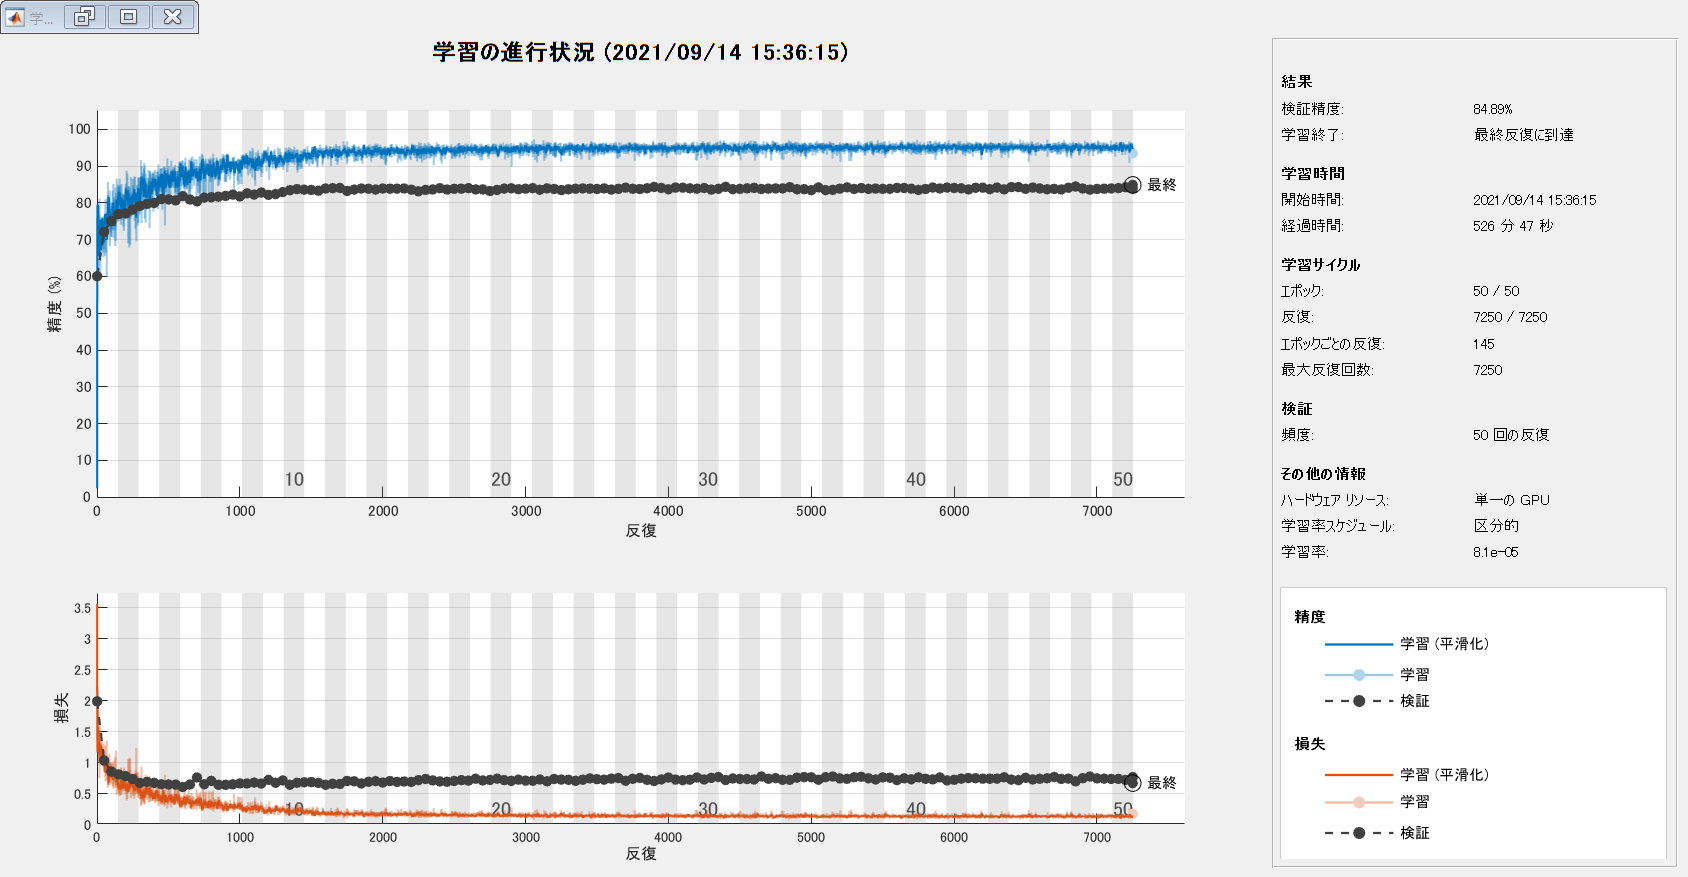

[net, info] = trainNetwork(pximds,lgraph,options);

## Test Network on One Image

As a quick sanity check, run the trained network on one test image. 

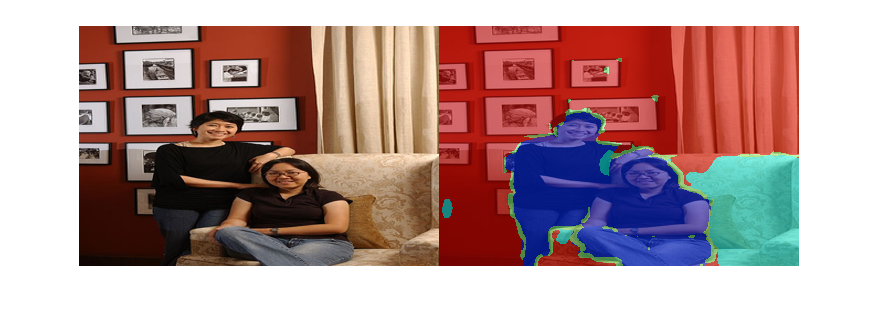

I = imresize(readimage(imdsTest,1),[240 360]);
C = semanticseg(I, net);
B = labeloverlay(I,C);
imshowpair(I,B,'montage')

Compare the results in `C` with the expected ground truth stored in `pxdsTest`. 

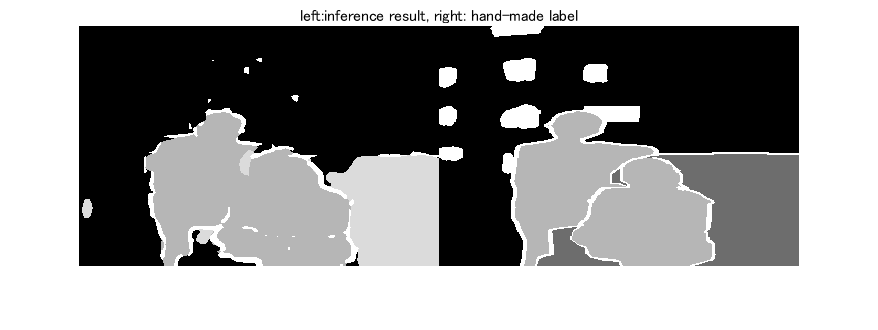

expectedResult = read(pxdsTest); pxdsTest.reset
actual = uint8(C);
expected = uint8(imresize(expectedResult{1}, [240 360]));
imshowpair(actual, expected,'montage');title('left:inference result, right: hand-made label')

Visually, the semantic segmentation results overlap well. The amount of overlap per class can be measured using the intersection-over-union (IoU) metric, also known as the Jaccard index. Use the  [`jaccard`](docid:images_ref.mw_fc8c8913-3141-4127-abf4-c7d90c72c870) function to measure IoU.

iou = jaccard(C,imresize(expectedResult{1},size(C)));
table(classes',iou)

ans = 22×2 table
         Var1            iou  
    _______________    _______

    {'background' }    0.86811
    {'aeroplane'  }        NaN
    {'bicycle'    }        NaN
    {'bird'       }        NaN
    {'boat'       }        NaN
    {'bottle'     }        NaN
    {'bus'        }        NaN
    {'car'        }        NaN
    {'cat'        }        NaN
    {'chair'      }          0
    {'cow'        }        NaN
    {'diningtable'}        NaN
    {'dog'        }        NaN
    {'horse'      }        NaN
    {'motorbike'  }        NaN
    {'person'     }    0.88904


Other common segmentation metrics include the [Dice index](docid:images_ref#mw_1ee709d7-bf6b-4ac9-8f5d-e7caf72497d4) and the [Boundary-F1](docid:images_ref#mw_53845c75-154c-4cbe-99c2-54ef222fecd7) contour matching score.

## Evaluate Trained Network

To measure accuracy for multiple test images, run[ `semanticseg`](docid:vision_ref.mw_bbecb1af-a6c9-43d1-91f5-48607edc15d1) on the entire test set. A mini-batch size of 10 is used to reduce memory usage while segmenting images. You can increase or decrease this value based on the amount of GPU memory you have on your system. If the GPU memory is not enough, please reduce the value. 

Make a folder called `SegmentationResult` to save the segmentation result. 

mkdir SegmentationResult

The segmentation results are saved in the directly specified as` [pwd,'\SegmentationResult']`. It means, the results are saved in the folder SegmeantationResult in the current directly. 

pxdsResults = semanticseg(augmentedImageDatastore([240 360],imdsTest),net, ...
    'MiniBatchSize',10, ...
    'WriteLocation',[pwd,'\SegmentationResult'], ...
    'Verbose',false);

## Calculate the semantic segmenation results

Use [ `evaluateSemanticSegmentation`](docid:vision_ref.mw_ec14c36c-b93d-4fde-8512-ea7d51651b89) to measure semantic segmentation metrics on the test set results. 

The labels in `pxdsTest` are not resized while the size of pxdsResults is 240 by 360 due to the resize function in augmentedImageDatastore. An error is returned when directly comparing the pxdsResults with pxdsTest because the image size is not same; hence the labels in pxdsTest were resized using the read function in the pxdsTest datastore. 

pxdsTest.ReadFcn=@(x) imresize(imread(x), [240 360]);
metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTest,'Verbose',false);

`evaluateSemanticSegmentation` returns various metrics for the entire dataset, for individual classes, and for each test image. To see the dataset level metrics, inspect `metrics.DataSetMetrics` .

metrics.DataSetMetrics

ans = 1×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.86525          0.63756        0.535       0.78113        0.59302  


The dataset metrics provide a high-level overview of the network performance. To see the impact each class has on the overall performance, inspect the per-class metrics using `metrics.ClassMetrics`.

metrics.ClassMetrics

ans = 22×3 table
                   Accuracy      IoU      MeanBFScore
                   ________    _______    ___________

    background     0.95558     0.88252       0.8358  
    aeroplane      0.69577     0.59989      0.71933  
    bicycle        0.18159     0.12859      0.35664  
    bird           0.80813     0.73137      0.51032  
    boat           0.44811     0.37829      0.19686  
    bottle         0.73369     0.61318      0.28872  
    bus            0.90064     0.81006      0.50036  
    car            0.80485     0.69297      0.30176  
    cat             0.8779     0.73347       0.4328  
    chair          0.21922     0.18007      0.14801  
    cow            0.64409      0.5792      0.39445  
    diningtable    0.50789     0.46026      0.19473  
    dog             0.7714     0.65037      0.31293  
    horse          0.58229     0.43126      0.24166  
    motorbike      0.67499     0.54206       0.2776  
    person         0.84563     0.68458      0.47346  


The animation below shows how BF score works. 

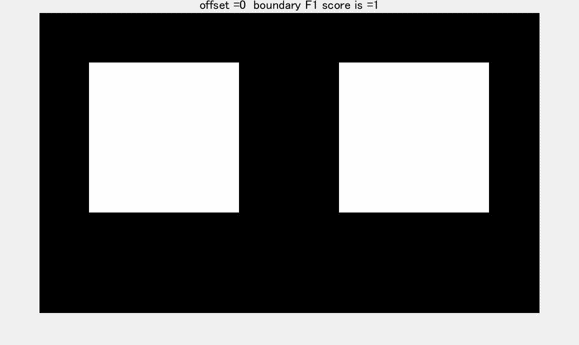

## Supporting Functions

## Deviding the image dataset into training, validation and test data

function [imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionPascalVOCData(imds,pxds,labelIDs)
% Partition CamVid data by randomly selecting 60% of the data for training. The
% rest is used for testing. 
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use 80 % of the images for training.
numTrain = round(0.8 * numFiles);
trainingIdx = shuffledIndices(1:numTrain);

% Use 10 % of the images for validation
numVal = round(0.1 * numFiles);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);

% Use the rest for testing.
testIdx = shuffledIndices(numTrain+numVal+1:end);

% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);

% Extract class and label IDs info.
classes = pxds.ClassNames;

% Create pixel label datastores for training and test.
trainingLabels = pxds.Files(trainingIdx);
valLabels = pxds.Files(valIdx);
testLabels = pxds.Files(testIdx);

pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsVal = pixelLabelDatastore(valLabels, classes, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classes, labelIDs);
end